clc
clear all
load("matlab4.mat")
load("matlab5.mat")
T0 = 100000;
T = T0;
flag = 1;
SAiter = 1;
arrayRmse(1) = inf;
arrayRmse(2) = inf;
arrayRmse(3) = inf;
arrayRmse(4) = inf;
arrayRmse(5) = inf;
arrayRmse(6) = inf;
arrayRmse(7) = inf;
arrayRmse(8) = inf;
while SAiter < 8 || flag
    a = 0.3;
    b = 0.1;
    c = 1;
    cnt = 1;
    K = 0.3;
    i = 0;
    pos1 = 1;
    pos2 = 1;
    temp = 0;
    index = 1;
    Length = 5;
    aaa = 0;
    ppp = 0;
    res = 0;
    TrainLimit = 4745;
    key = 0;
    limit1 = 0.5;
    limit2 = 0.03;
    xseries = 1:4745;
    xseries2 = 1:1378;
    u = 0;
    for j = 1:4
        res(j) = 0;
    end
    for j = 1:4745
        y(j) = PekingTemp(j);
    end
    YReal = 0;
    for j = 4746:6123
        YReal(j-4745) = PekingTemp(j);
    end
    % while true
        deltaT = K * T;
        while index + Length < TrainLimit
            i = i + 1;
            for j = 1:Length
                dy(j) = abs(y(index) - Fourier_8(index));
                s2(j) = dy(j) * dy(j);
                temp = temp + s2(j);
                index = index + 1;
            end
            u(i) = temp;
            temp = 0;
            if i < 4 || u(i) > res(i)
                if i == 1
                    res(i+1) = u(i);
                    continue;
                end
                P = 5*exp(-abs(u(i)-u(i-1))/deltaT);
                P = P - 4.1;
                re_P(cnt) = P;
                cnt = cnt + 1;
                seed = rand(1);
                if seed > P || i < 4
                    forward1 = index - Length;
                    for j = 1:Length
                        forward1 = forward1 + 1;
                        fy(forward1) = y(forward1);
                        key = key + 1;
                    end
                    index = index - Length + 1;
                    if i > 4
                        num = c * (vvGM(u));
                        res(i+1) = num(i+1);
                    else
                        res(i+1) = u(i);
                    end
                    continue;
                end
            end
            forward2 = index - Length + 1;
            for j = 1:Length
                ERR(j) = dy(j) / y(forward2);
                if ERR(j) > limit1
                    a = a * (1 + b * abs(tanh(ERR(j) - limit1)));
                elseif ERR(j) < limit2
                    a = a * (1 - b * abs(tanh(ERR(j) - limit2)));
                    if a < 0.01
                        a = 0.01;
                    end
                end
                if a < 10
                    aaa(pos2) = a;
                    pos2 = pos2 + 1;
                end
                gamma(j) = a * dy(j);
                if gamma(j) > dy(j)
                    gamma(j) = dy(j);
                end
                if y(forward2) > Fourier_8(forward2)
                    fy(forward2) = y(forward2) - gamma(j);
                else 
                    fy(forward2) = y(forward2) + gamma(j);
                end
                forward2= forward2 + 1;
            end
            num = c * (vvGM(u));
            res(i+1) = num(i+1);
        end
%         if index < 4745
            for j = 4745 : -1 : index - Length
                fy(index) = y(index);
                index = index - 1;
            end
%         end
    %     plot(xseries,y,xseries,fy)
    indx = 1;
    temp = 0;
    for i = 1:13
        for j = 1:12
            index_month = (i-1)*12+j;
            for k = 1:30
                index_day = (i-1)*365+(j-1)*12+k;
                temp = temp + fy(index_day);
            end
            data(index_month) = temp/30;
            temp = 0;
        end
    end
    
    hold off
    n_year=13; %length of data set
    slen=12; %seasonal length
    
    b0=[];
    for i=1:slen
        b0=[b0 (data(i+slen)-data(i))/slen];
    end
    b0=sum(b0)/slen; % initial trend, here average of trend across seasons
    
    ap=[];
    for j=1:n_year
        ap=[ap sum(data(slen*(j-1)+1:slen*j))/slen];
    end % averages of each year
    
    ym=zeros(slen,n_year);
    for j=1:n_year
        for i=1:slen
            ym(i,j)=data(i+(j-1)*slen)/ap(j);
        end
    end % division by appropriate yearly mean
    I=[];
    for i=1:slen
            I=[I sum(ym(i,:))/n_year];
    end % initial seasonal components
    
    n_pred=12*4; %forecasting period
    
    
    alpha=0.05;
    beta=0.05;
    gamma=0.05;
    p=[alpha beta gamma]; %calibration parameters
    X0=[p data n_pred b0 I slen]; %initial values
        
    options.Display='iter';
    options.FunValCheck='on';
    options.PlotFcns=@optimplotfval;
    numbruns=200*length(p);
    options.MaxFunEvals=numbruns;
    options.MaxIter=numbruns;
    
    minFunc = @(p)holtwinters(p,data,n_pred,b0,I,slen);
    [x,fval,exitflag,output]=fminsearch(minFunc,p,options)
    
    [ee,ts]=holtwinters(x,data,n_pred,b0,I,slen);
    
    % % visualisation of results
    % figure(2)
    % plot(data)
    % hold on
    % plot(ts,'--r')
    temp = 0;
    YPred = 0;
    indx = 1;
    each = 0;
    for i = 1:4
        for j = 1:12
            iii = 156+(i-1)*12+j;
            temp = temp + ts(iii);
        end
        YPred(indx) = temp/12;
        indx = indx + 1;
        temp = 0;
    end
    for i = 14:17
        for j = 1:345
            index = 4745+(i-14)*345+j;
            each = each + PekingTemp(index);
        end
        each_year_latter_ave(i-13) = each / 345;
        YReal(i-13) = each / 345;
        each = 0;
    end
    YReal = 0;
    mae = mean(abs(YReal - YPred))
    sse = sum((YPred - YReal).^2)
    rmse = sqrt(mean((YPred-YReal).^2))
    meap = mean(abs((YReal - YPred)./YReal))*100 
    SAiter = SAiter + 1;
    arrayRmse(SAiter) = rmse; 
    T = T - K*T
    if SAiter > 8

        flag = 0;

%         for iii = 1:3
%              if arrayRmse(SAiter-iii+1) > arrayRmse(SAiter-iii)
%                  break
%              end
%              if iii == 3
%                  flag = 0;
%              end
%         end
    end
end
SAiter

%%%%%%


YReal = 0;
fy(4745) = fy(4744);
for i = 1:4745
    yyyy(i) = fy(i);
end
for i = 4746:6125
    yyyy(i) = PekingTemp(i);
end
for i = 4746:6125
    YReal(i-4745) = PekingTemp(i);
end
for i = 1 : 4745
    data(i) = fy(i);
end
plot(data)


% indx = 1;
% temp = 0;
% for i = 1:13
%     for j = 1:12
%         index_month = (i-1)*12+j;
%         for k = 1:30
%             index_day = (i-1)*365+(j-1)*12+k;
%             temp = temp + fy(index_day);
%         end
%         data(index_month) = temp/30;
%         temp = 0;
%     end
% end

hold off
    n_year=13; %length of data set
    slen=365; %seasonal length
    
    b0=[];
    for i=1:slen
        b0=[b0 (data(i+slen)-data(i))/slen];
    end
    b0=sum(b0)/slen; % initial trend, here average of trend across seasons
    
    ap=[];
    for j=1:n_year
        ap=[ap sum(data(slen*(j-1)+1:slen*j))/slen];
    end % averages of each year
    
    ym=zeros(slen,n_year);
    for j=1:n_year
        for i=1:slen
            ym(i,j)=data(i+(j-1)*slen)/ap(j);
        end
    end % division by appropriate yearly mean
    I=[];
    for i=1:slen
            I=[I sum(ym(i,:))/n_year];
    end % initial seasonal components
    
    n_pred=1380; %forecasting period
    
    
    alpha=0.05;
    beta=0.05;
    gamma=0.05;
    p=[alpha beta gamma]; %calibration parameters
    X0=[p data n_pred b0 I slen]; %initial values
        
    options.Display='iter';
    options.FunValCheck='on';
    options.PlotFcns=@optimplotfval;
    numbruns=200*length(p);
    options.MaxFunEvals=numbruns;
    options.MaxIter=numbruns;
    
    minFunc = @(p)holtwinters(p,data,n_pred,b0,I,slen);
    [x,fval,exitflag,output]=fminsearch(minFunc,p,options)
    
    [ee,ts]=holtwinters(x,data,n_pred,b0,I,slen);
    


SAGMH_DATA = data;
SAGMSAR_DATA = data;

YPred = 0;
for i = 4746 : 6125
    YPred(i - 4745) = ts(i);
end



mae = mean(abs(YReal - YPred))
sse = sum((YPred - YReal).^2)
rmse = sqrt(mean((YPred-YReal).^2))
meap = mean(abs((YReal - YPred)./YReal))*100


YReal = 0;
YPred = 0;
[data(len-predLen) + NonstationaryTrend(len - predLen) ; YY(1:end-1) + p_coef(1) * t(len - predLen+1:len) + p_coef(2)]
temppp = ans
plot(temppp)
for i = 1 : 1380
    YReal(i) = PekingTemp(i + 4745);
end

for i = 1 : 1380
    YPred(i) = temppp(i);
end


mae = mean(abs(YReal - YPred))
sse = sum((YPred - YReal).^2)
rmse = sqrt(mean((YPred-YReal).^2))
meap = mean(abs((YReal - YPred)./YReal))*100

YReal = 0;
YPred = 0;
[data(len-predLen) + NonstationaryTrend(len - predLen) ; YY(1:end-1) + p_coef(1) * t(len - predLen+1:len) + p_coef(2)]

ans =     5.1168
    3.4742
    4.2202
    6.8669
    3.0727
   -1.8724
   -3.7201
    3.7705
    5.6831
   10.2661


temppp = ans

temppp =     5.1168
    3.4742
    4.2202
    6.8669
    3.0727
   -1.8724
   -3.7201
    3.7705
    5.6831
   10.2661


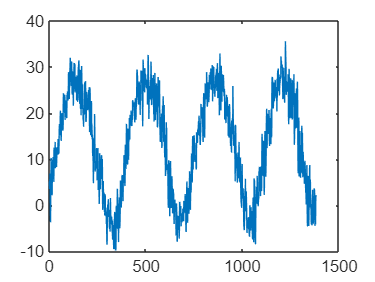

plot(temppp)


cnt = 1;
for deltaD = 60:1:75
    for i = 1 : 1380
        YReal(i) = PekingTemp(i + 3365 - deltaD);
    end
    
    for i = 1 : 1380
        YPred(i) = temppp(i);
    end
    
    
    mae11(cnt) = mean(abs(YReal - YPred));
    sse11(cnt) = sum((YPred - YReal).^2);
    rmse11(cnt) = sqrt(mean((YPred-YReal).^2));
    meap11(cnt) = mean(abs((YReal - YPred)./YReal))*100;
    cnt = cnt + 1;
end
min(rmse11)

ans = 4.6832

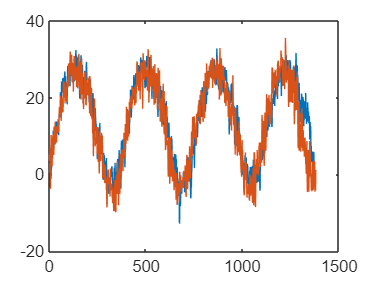

xxx = 1:1380;
plot(xxx,YReal,xxx,YPred)